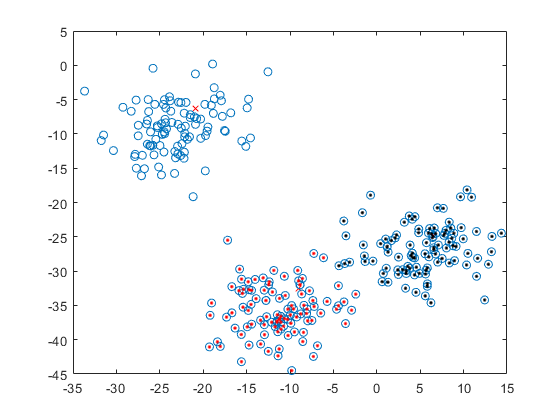

A=300;
CentrosReales=10*2*(randn(2,3)-0.5);
desviaciones=2*2*(randn(2,A)-0.5);
index1=1:A/3;
index2=A/3+1:2*A/3;
index3= 2*A/3+1:A;

Puntos=CentrosReales(:,1)+desviaciones(:,index1);
Puntos=[Puntos,CentrosReales(:,2)+desviaciones(:,index2)];
Puntos=[Puntos,CentrosReales(:,3)+desviaciones(:,index3)];

plot(CentrosReales(1,:),CentrosReales(2,:),'rx')
hold on
plot(Puntos(1,:),Puntos(2,:),'o');
plot(Puntos(1,index1),Puntos(2,index1),'.r');
plot(Puntos(1,index2),Puntos(2,index2),'.k');

entradas=Puntos;

deseados=[[zeros(1,length(index1));zeros(1,length(index1))],[zeros(1,length(index2));ones(1,length(index2))],[ones(1,length(index3));zeros(1,length(index3))]];

% revolver
index=randperm(A);
entradas=entradas(:,index);
deseados=deseados(:,index);

